## Po co splot i autokorelacja

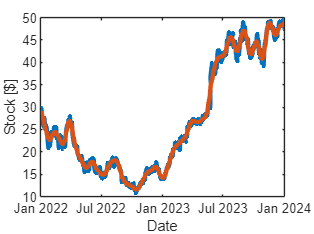

load('NVIDIA_stock.mat');
y1 = NVIDIA_close;
y2 = fir1(60,0.1);
y = conv(y1,y2);
D = finddelay(y1,y);
y = y(1+D:length(y)-D);

figure;
plot(NVIDIA_date,y1,'LineWidth',3)
hold on;
plot(NVIDIA_date,y,'LineWidth',3)
xlim([datetime('2022','format','uuuu') datetime('2024','format','uuuu')])
ylabel('Stock [$]')
xlabel('Date')
saveas(gcf,'splot1.png')

Autokorelacja:

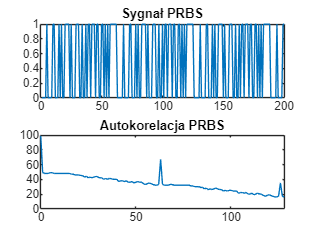

N = 200;
O = 6;
dt = 0.1;
t = 0:dt:(dt*(N-1));
P=prbs(O,N);

[Rxx,dels] = xcorr(P);

figure('Color','w');
subplot(2,1,1);
plot(P);
title('Sygnał PRBS')

subplot(2,1,2);
plot(dels,Rxx);
xlim([0 2*2^O])
title('Autokorelacja PRBS')

Korelacja:

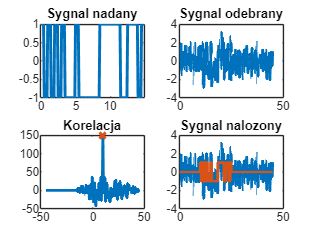

N = 30;
UF = 5;
D1 = 100;
D2 = 200;
dt = 0.1;
t = 0:dt:(dt*(N*UF-1));
t2 = 0:dt:(dt*((N*UF+D1+D2)-1));
bits = 2*(randi(2,N,1)-1.5);
syg = repmat(bits,1,UF)';
syg = syg(:);
SNR = -3;
syg_with_del = [zeros(D1,1); syg;zeros(D2,1)];
syg_received = awgn(syg_with_del,SNR,'measured');

[Rxy,dels] = xcorr(syg_received,syg);
[mx,ix] = max(Rxy);

LW = 2;
figure;
subplot(2,2,1)
plot(t,syg,'LineWidth',LW)
title('Sygnal nadany')
subplot(2,2,2)
plot(t2,syg_received,'LineWidth',LW)
title('Sygnal odebrany')
subplot(2,2,3)
plot(dels*dt,Rxy,'LineWidth',LW)
hold on;
plot(dels(ix)*dt,mx,'x','LineWidth',LW)
title('Korelacja')
subplot(2,2,4)
plot(t2,syg_received,'LineWidth',LW)
hold on;
plot(t2,syg_with_del,'LineWidth',LW)
title('Sygnal nalozony')
saveas(gcf,'korelacja1.png')

## Zadanie 0

autosplot rect(t).

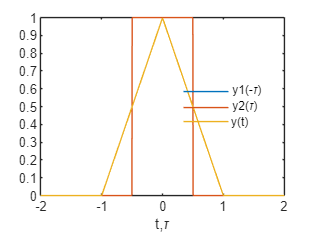

T = 1;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) rectpuls(t);
y2 = y1;
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(-tau))
hold on;
plot(tau,y2(tau))
plot(t,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'},'Location','best','Box','off')
xlabel('t,\tau')
saveas(gcf,'Zad_00.png')

## Zadanie 1

Liczenie splotu rect(t-1) z u(t).

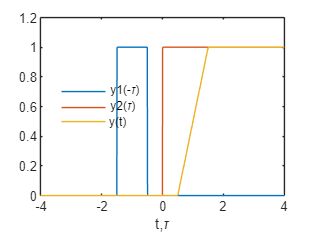

T = 2;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) rectpuls(t-1);
y2 = @(t) heaviside(t);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(-tau))
hold on;
plot(tau,y2(tau))
plot(t,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'},'Location','best','Box','off')
xlabel('t,\tau')
saveas(gcf,'Zad_01.png')

## Zadanie 2

Liczenie splotu rect(t-1-a) z u(t).

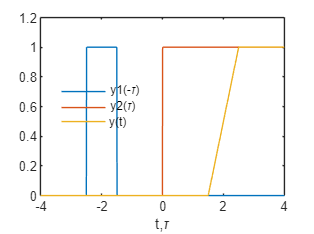

T = 2;
a = 1;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) rectpuls(t-1-a);
y2 = @(t) heaviside(t);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(-tau))
hold on;
plot(tau,y2(tau))
plot(t,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'},'Location','best','Box','off')
xlabel('t,\tau')
saveas(gcf,'Zad_02.png')

## Zadanie 3

Liczenie splotu exp(-t)u(t) z rect(t-0.5).

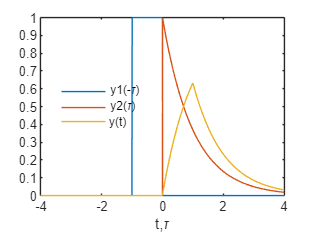

T = 2;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) rectpuls(t-0.5);
y2= @(t) exp(-t).*heaviside(t);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(-tau))
hold on;
plot(tau,y2(tau))
plot(t,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'},'Location','best','Box','off')
xlabel('t,\tau')
saveas(gcf,'Zad_03.png')

## Zadanie 5

Liczenie splotu

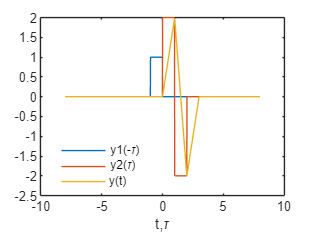

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y2 = @(t) 2*heaviside(t)-4*heaviside(t-1)+2*heaviside(t-2);
y1 = @(t) heaviside(t)-heaviside(t-1);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(-tau))
hold on;
plot(tau,y2(tau))
plot(t,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'},'Location','best','Box','off')
xlabel('t,\tau')
saveas(gcf,'Zad_05.png')

## Zadanie 6

Liczenie splotu

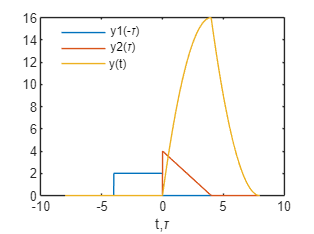

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) 2*heaviside(t)-2*heaviside(t-T);
y2 = @(t) (T-t).*rectpuls((t-T/2)/T);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(-tau))
hold on;
plot(tau,y2(tau))
plot(t,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'},'Location','best','Box','off')
xlabel('t,\tau')
saveas(gcf,'Zad_06.png')

## Zadanie 7

Liczenie splotu

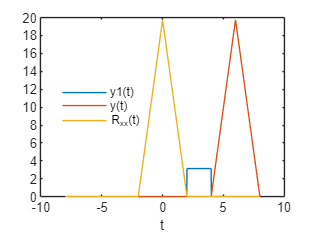

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) pi*rectpuls((t-3)/2);
y2 = y1;
y = zeros(size(t));
yxx = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
    yxx(i)= sum(y1(tau-tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(tau))
hold on;
plot(t,y)
plot(t,yxx)
legend({'y1(t)','y(t)','R_{xx}(t)'},'Location','best','Box','off')
xlabel('t')
saveas(gcf,'Zad_07.png')

## Zadanie 8

Liczenie splotu

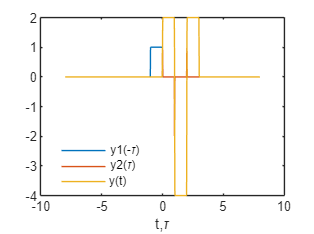

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y2 = @(t) gradient(2*heaviside(t)-4*heaviside(t-1)+2*heaviside(t-2))/dtau;
y1 = @(t) heaviside(t)-heaviside(t-1);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y2(tau))*dtau;
end

figure;
plot(tau,y1(-tau))
hold on;
plot(tau,y2(tau)*dtau)
plot(t,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'},'Location','best','Box','off')
xlabel('t,\tau')
saveas(gcf,'Zad_08.png')

## Zadanie 9

Autosplot exp(-t)u(t)

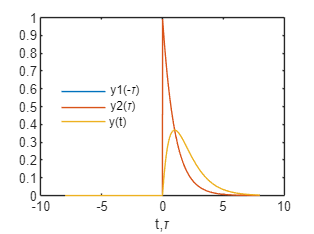

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) heaviside(t).*exp(-t);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(-tau+tcurr).*y1(tau))*dtau;
end

figure;
plot(tau,y1(tau))
hold on;
plot(tau,y1(tau))
plot(tau,y)
legend({'y1(-\tau)','y2(\tau)','y(t)'},'Location','best','Box','off')
xlabel('t,\tau')
saveas(gcf,'Zad_09.png')

## Zadanie 10

Liczenie autokorelacji

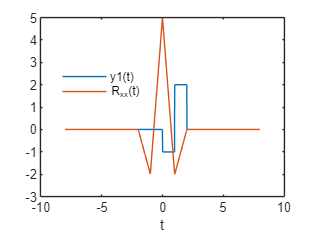

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) -heaviside(t)+3*heaviside(t-1)-2*heaviside(t-2);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(tau-tcurr).*y1(tau))*dtau;
end

figure;
plot(tau,y1(tau))
hold on;
plot(tau,y)
legend({'y1(t)','R_{xx}(t)'},'Location','best','Box','off')
xlabel('t')
saveas(gcf,'Zad_10.png')

## Zadanie 11

Liczenie autokorelacji

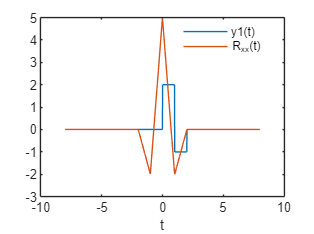

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) 2*heaviside(t)-3*heaviside(t-1)+1*heaviside(t-2);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(tau-tcurr).*y1(tau))*dtau;
end

figure;
plot(tau,y1(tau))
hold on;
plot(tau,y)
legend({'y1(t)','R_{xx}(t)'},'Location','best','Box','off')
xlabel('t')
saveas(gcf,'Zad_11.png')

## Zadanie 12

Liczenie autokorelacji

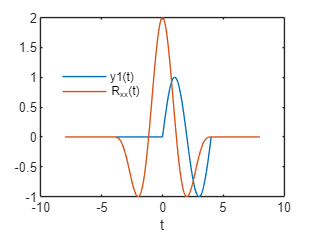

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) sin(pi*t/2).*rectpuls((t-2)/4);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(tau-tcurr).*y1(tau))*dtau;
end

figure;
plot(tau,y1(tau))
hold on;
plot(tau,y)
legend({'y1(t)','R_{xx}(t)'},'Location','best','Box','off')
xlabel('t')
saveas(gcf,'Zad_12.png')

## Zadanie 13

Liczenie autokorelacji

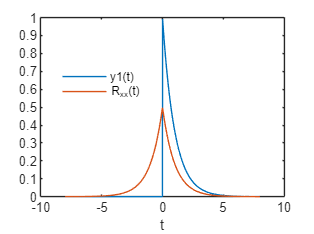

T = 4;

tau = linspace(-2*T,2*T,1000);
dtau = mean(diff(tau));

t = tau;
y1 = @(t) exp(-t).*heaviside(t);
y = zeros(size(t));

for i=1:length(t)
    tcurr = t(i);
    y(i) = sum(y1(tau-tcurr).*y1(tau))*dtau;
end

figure;
plot(tau,y1(tau))
hold on;
plot(tau,y)
legend({'y1(t)','R_{xx}(t)'},'Location','best','Box','off')
xlabel('t')
saveas(gcf,'Zad_13.png')